# Two-Sample T-Tests

*Bart Krekelberg - Last Update Jan 2023.*

Two sample tests compare measurements taken in one condition and compare them to the measurements taken in another condition. For instance, a behavioral measure before and after treatment with some drug, or neural activity with and without directed attention. 

In this chapter we will look at the underlying methods as well as the Matlab functions that implement these tests in an efficient and easy to use manner. 

## Two-Sample Tests

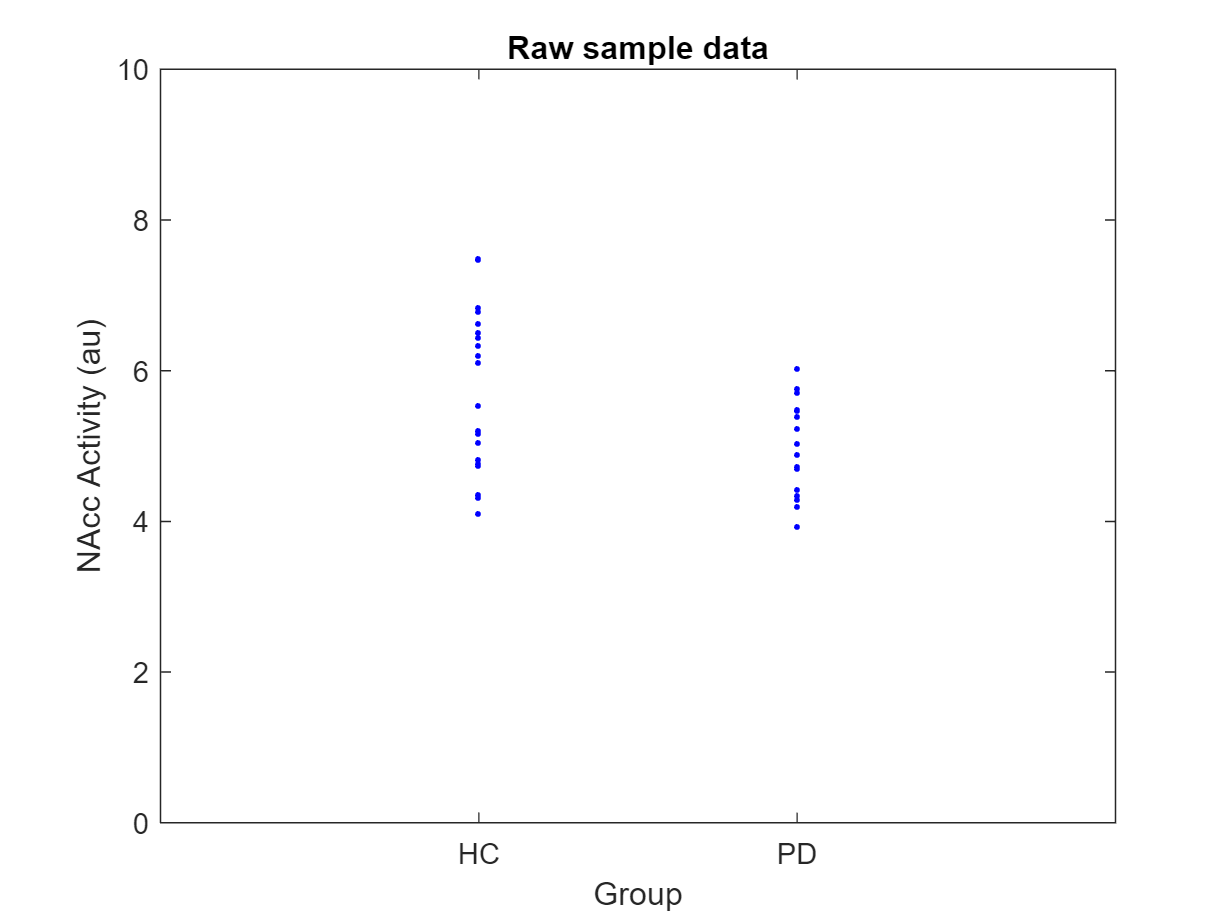

clear variables;
rng(1230,'twister'); % Keep random numbers repeatable between runs

% You performed an experiment in which you measured the PET signal in the
% NAcc in 20 patients with Parkinson's (PD) and in 20 normal controls (HC).
nrPatients = 20;
nrControls = nrPatients;
naccPD = 5 + randn(nrPatients,1); % Generate fake data.
naccHC = 6   + randn(nrControls,1);

% Create a figure to show the raw samples.
figure(2);
clf;
plot(ones(1,nrControls),naccHC,'b.');
hold all
plot(2*ones(1,nrPatients),naccPD,'b.')
xlabel('Group')
set(gca,'XTick',[1 2],'XTickLabel',{'HC','PD'},'XLim',[0 3],'ytick',0:2:10,'ylim',[0 10]);
ylabel 'NAcc Activity (au)'
title 'Raw sample data'


meanNaccPD = mean(naccPD)

meanNaccPD = 5.0225

meanNaccHC = mean(naccHC)

meanNaccHC = 5.7446

sampleDifference = meanNaccPD-meanNaccHC;

The mean of the samples is different, but can you conclude that activity in the NAcc in PD patients is less than that of healthy controls? 

The first step towards a Monte Carlo statistical test is to ask how often such a difference in the means of the samples occurs just by chance. To investigate this, we create simulated data sets which are all drawn from the same underlying population:

nrSimulatedSets = 10000;
nullSamples     =  randn(nrPatients,nrSimulatedSets);
nullMeans       = mean(nullSamples);

Under the null hypothesis, the PD and HC samples were randomly selected from one of the columns of `nullSamples`. Based on that we can determine what kind of differences in mean one should expect. The following vectorized code calculates all pairwise differencs of the nullMeans. 

X = repmat(nullMeans,[nrSimulatedSets 1]);
allDifferences = X-X';
[col,row] = meshgrid(1:nrSimulatedSets,1:nrSimulatedSets);
allDifferences(col==row) =[];

Let's look at a histogram of these differences (i.e. the null distribution).

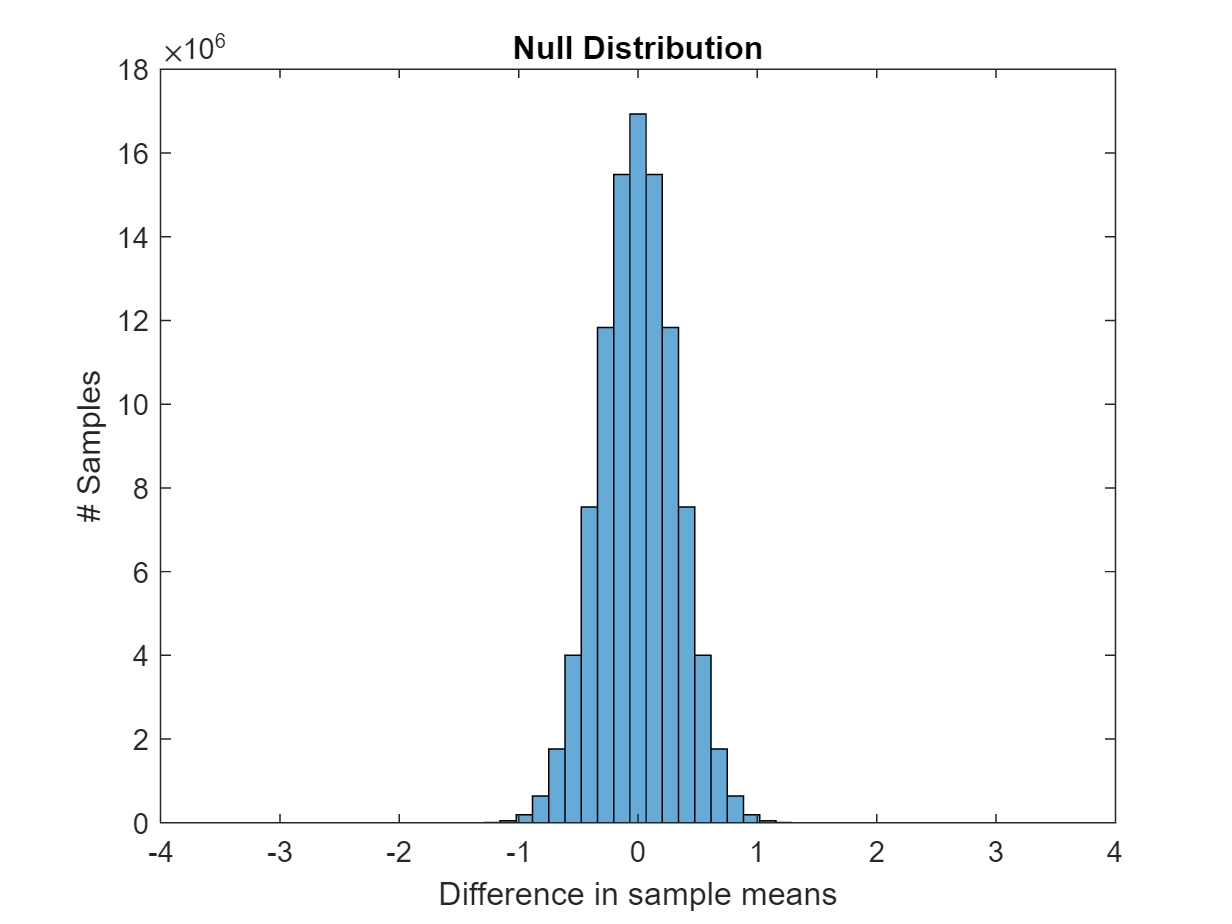

figure
nrBins = 25;
[n,binEdges] = histcounts(allDifferences,nrBins);
topOfBin = binEdges(2:end);
histogram('BinEdges',binEdges,'BinCounts',n);
set(gca,'XLim',[-4 4])
xlabel 'Difference in sample means'
ylabel '# Samples'
title 'Null Distribution'

This shows that a difference of zero is most prevalent (under the null hypothesis) but differences of $$\pm 0.5 $$ are not infrequent. Just as with the one-sample test, we can estimate the relative frequency as well as the cumulative frequency of a certain difference in means, and compare it to the difference we observed.

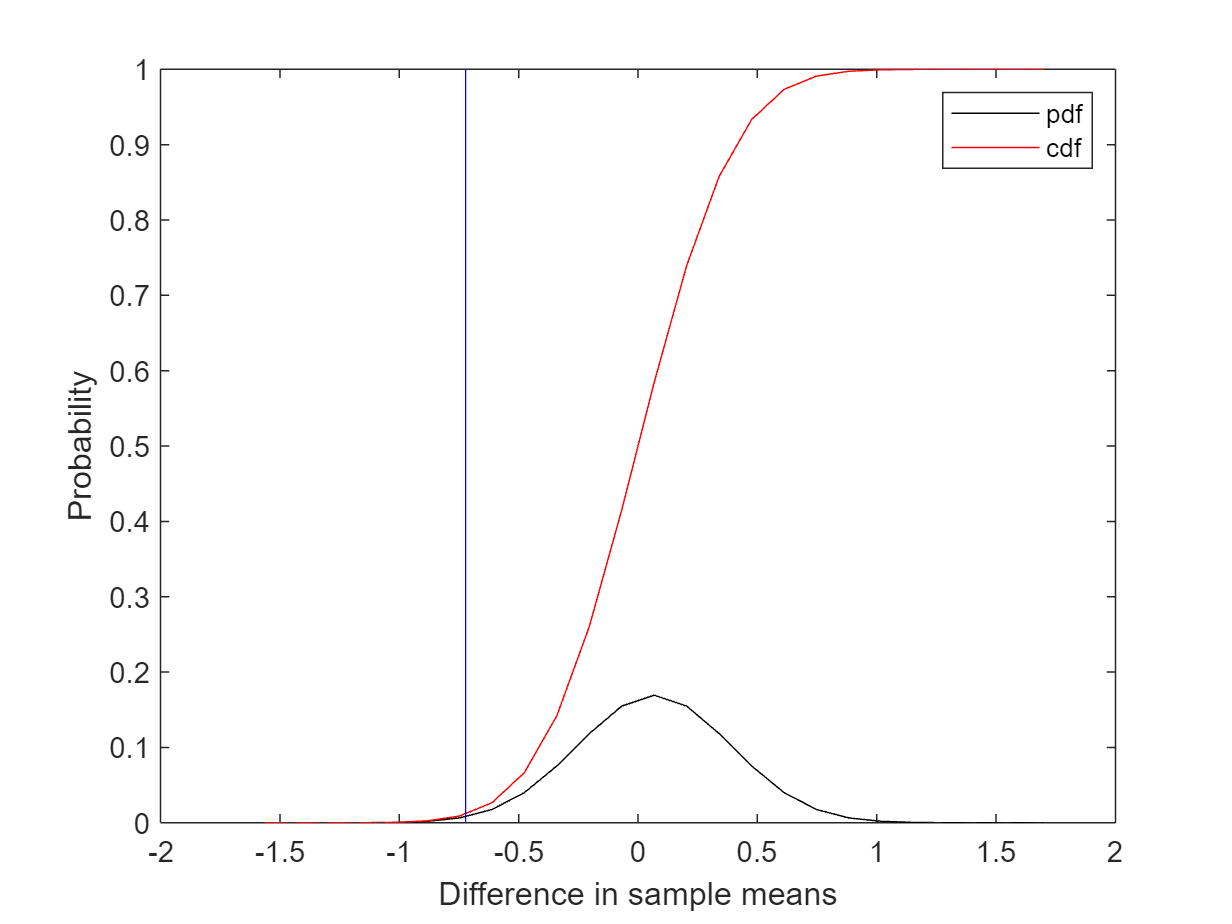

figure
pdf = n./sum(n);
cdf = cumsum(n)./sum(n);
plot(topOfBin,pdf,'k');
hold on;
plot(topOfBin,cdf,'r');
plot([sampleDifference sampleDifference],get(gca,'Ylim'),'b');
xlabel 'Difference in sample means'
ylabel 'Probability'
legend('pdf','cdf')

Is the difference large enough? First, find the last point on the CDF that is still just below the observed sample difference and then evaluate the cdf at that point

lastSmallerIx =find(topOfBin<sampleDifference,1,'last');
pSmaller  = cdf(lastSmallerIx)

pSmaller = 0.0090

So the probablity of observing a difference in means as negative as the observed value or less is `pSmaller`. Because our hypothesis **before we saw the data** was that the NAcc activity was *less* than the activity of PD patients we can reject the null hypothesis of equal means at the 0.05 significance level if `pSmaller<0.05`.

This is called a one-tailed test; based on what we knew before doing the experiment we decided to test the hypothesis that mean actvitiy in NAcc is *less* in PD than HC. Based on this prior hypothesis we *only* look at the left tail of the CDF, and use it to reject the null hypothesis. 

If, however, your hypothesis is less specific (e.g. you are looking at another area where activity may go up or down in PD patients, and you just want to know whether it was *different* (larger or smaller) then you would first look at the left tail (is the observed difference in means less than expected by chance) and then at the right tail (is the observed difference in means more than expected by chance). If you set a 0.05 threshold for both comparisons then you're risk of a false positive (detecting a difference even though the samples were drawn from the same population) would be 0.1 not 0.05. In other words if you are doing a two-tailed test at a significance level of 0.05, your threshold for rejecting the null hypothesis should be 0.025 on the left tail and 0.025 on the right tail, such that the total risk of reporting a false positive is less than 0.05 (or whatever significance level you choose).

## The Two-Sample T-Test

In the Monte Carlo simulations we chose our own test statistic (the difference in sample means), and compared it to a null distribution. In the Student T-Test the statistic is a combination of the difference in sample means and the standard errror:


$$T = \frac{\bar{x}_1 -\bar{x}_2}{\sqrt{(s_1^2 +s_2^2)/n}} $$


The null distribution of this statistic is the T distribution with 2n-2 degrees of freedom. In Matlab we can calculate this statistic for our PD and HC samples, and determine its cumulative probability using the `tcdf` function:

nrMeasurements = numel(naccPD);
se = sqrt((std(naccPD).^2+std(naccHC).^2)/nrMeasurements);
T = (meanNaccPD-meanNaccHC)./se;
p = tcdf(T,2*nrMeasurements-2)

p = 0.0065

This explicit calculation shows how the T statistics expresses the observed difference in sample means (`meanNaccPD-meanNaccHC`) in terms of the standard error `se` . In other words, it is a measure of *how different the sample means are relative to our intrinsic ability to measure such differences*. With larger standard deviations our ability to reliably estimate a mean goes down, and with more measurements the ability to reliably estimate a mean goes up.

In practice you do not perform T-Tests in this way in Matlab but you use the built-in `ttest2` function, which returns the same p-value.

[~,p]=  ttest2(naccPD,naccHC,'tail',-1)

p = 0.0065

This function also automatically deals with different sample sizes (e.g. if you had more PD patients than HC).

Note that this uses the `ttest2` function not `ttest`. The latter also tests the hypothesis that the sample means are different, but it assumes that you used repeated measurements. For instance, if you measured NAcc activity in the same PD patients before and after L-Dopa administration, then you would use paired t-test to determine whether the mean activity before treatment and after treatment are significantly different. More on this later. 